This code runs the method of characteristics back one step if the characteristic stays inside the grid, and until it comes back inside the grid (all the way to the initial time if neccessary). 

First we set the dimension and the bounds in each dimension

dims = 2;
% bounds = [-2 2; -2 2; -pi/3 pi/3]; % chaplygin
% bounds = [-sqrt(2) sqrt(2); -pi/3 + 0.01 pi/3 - 0.01]; % reduced chaplygin
 bounds = [0 2; -2 2]; % bouncing ball
% bounds = [0 125; 0 125; 75 125]; % SIR 3D
 %bounds = [0 1; 0 1] % reduced SIR
N = 75;

And we generate a uniform grid with $N$points in each dimension

grid = zeros(dims, N);
for i = 1:dims
    grid(i, :) = linspace(bounds(i, 1), bounds(i, 2), N);
end

Create a time array and set the integration step $\Delta t$

T = 10;
N_T = 50;
dt = T/N_T;

Initialize arrays to hold the solution $u\left(t,x\right)$ at each time step

if dims == 2
    u = zeros(N_T, N, N);
end
if dims == 3
    u = zeros(N_T, N, N, N);
end

Initialize the solution at time 0 with the initial density 

if dims == 3
for i = 1:N
    for j = 1:N
        for k = 1:N
            u(1, i, j, k) = initial_density([grid(1, i), ...
                grid(2, j), grid(3, k)]);
        end
    end
end
end
 if dims == 2
     for i = 1:N
         for j = 1:N
             u(1, i, j) = initial_density([grid(1, i), grid(2, j)]);
         end 
     end
 end



Suppose we have the values of $u$ up to $t$. And now we want to find them at a point $t+\Delta t$. For each element $x$ in the grid:

- Run the characteristics backward starting from $x$ back for $\Delta t$.

- Find the element on the grid closest to where the characteristic lands $x_{\textrm{grid}}$

- If $x_{\textrm{grid}} \;$ is not inside the grid anymore run the characteristics backwards again for $\Delta \;t$starting from $x_{\textrm{grid}} \;$ this time

- Update the value by the following rule if no impact happened

                   
$$$$u(t + \Delta t, x) = u(t, \varphi_{-\Delta t}^\mathcal{H}(x)) + \Delta t  c(\varphi_{-\Delta t}^\mathcal{H}(x),  u(t, \varphi_{-\Delta t}^\mathcal{H}(x))  )$$ $$ \approx u(t, x_{grid}) + \Delta t c(x_{grid}, u(t, x_{grid}))$$$$


         4. If an impact has happened multiply the result by the hybrid jacobian

Notes:

- if the trajectory stays inside the grid for a step then impacts_on_traj should have length 1 (you only go once through the while loop) and it indicated whether an impact happened between x_new and x_old. 

- current_traj has length of impacts_on_traj + 1. If it stays inside the grid the length should be 2. 

- when the while loop is done the value of index_grid and x_prev are the values of the point in the grid which is at the base of the characteristic. We start integration from there


$$$u_{i + 1} = u_i - \Delta t \ ( u_i(1 - impact_i) + u_i \ \mathcal{J}_\mu^X (x_i)  * impact_i) \  div_\mu(X) (x_i)$$$


So if an impact has happened then ${\textrm{impact}}_i$  = 1 and the first term vanishes. 

 if dims == 3
 for t = 2:N_T
     t
     for i = 1:N
         i
         for j = 1:N
             for k  = 1:N
                x_now = [grid(1, i), grid(2, j), grid(3, k)];
                
                % run characteristics until we get inside the grid
                out_of_grid = 1;
                current_traj = x_now;
                impacts_on_traj = [];
                length = 1;
                while out_of_grid == 1 && length < t
                    out_of_grid = 0;
                    % run one time step
                    [x_old, is_impact]  = run_backward...
                        (x_now, dt, @ reset_map, @impact, @eom);
                    % determine position on grid
                    [x_prev, index_grid] = ...
                         closest_grid_point...
                         (x_old, {N, bounds});

                    % find if characteristic went out of grid
                    if any(index_grid > N) || ...
                            any(index_grid < 1)
                        out_of_grid = 1;
                        
                    end

                    % remember info at previous time step
                    current_traj = [current_traj; x_prev];
                    impacts_on_traj = [impacts_on_traj, is_impact];
                    x_now = x_old;
                    length = length + 1;

                end
                
                % integrate backwards
                if length == t
                    u_val = initial_density(current_traj(end, :));
                else
                    u_val = u(t - length + 1,...
                        index_grid(1), index_grid(2), ...
                        index_grid(3));
                end

                for l = length - 1:-1:1
                    u_val = u_val + dt*div_X(current_traj(l, :),...
                        u_val*(1 - impacts_on_traj(l)*(...
                        1 - hybrid_jacobian(current_traj(l, :)))));
                end
               u(t, i, j, k) = u_val;
             end
         end
     end
 end
 end


t = 2

t = 3

t = 4

t = 5

t = 6

t = 7

t = 8

t = 9

t = 10

t = 11

t = 12

t = 13

t = 14

t = 15

t = 16

t = 17

t = 18

t = 19

t = 20

t = 21

t = 22

t = 23

t = 24

t = 25

t = 26

t = 27

t = 28

t = 29

t = 30

t = 31

t = 32

t = 33

t = 34

t = 35

t = 36

t = 37

t = 38

t = 39

t = 40

t = 41

t = 42

t = 43

t = 44

t = 45

t = 46

t = 47

t = 48

t = 49

t = 50

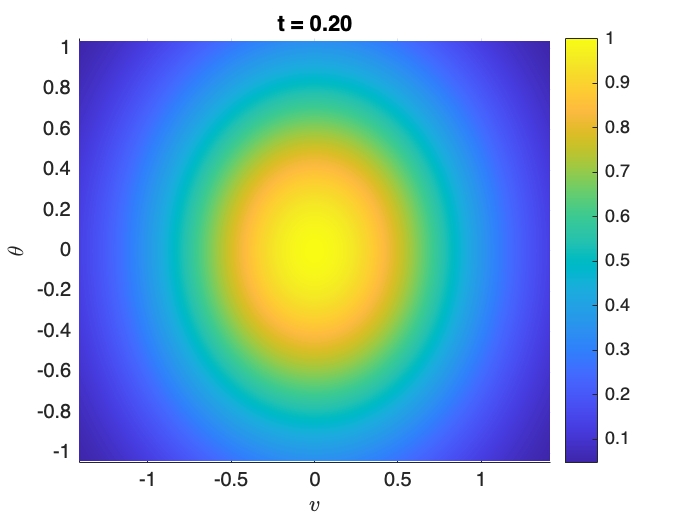

tic
 if dims == 2

    for t = 2:N_T
        t
        for i = 1:N
            
            for j = 1:N
                x_now = [grid(1, i), grid(2, j)];
                
                % run characteristics until we get inside the grid
                out_of_grid = 1;
                current_traj = x_now;
                impacts_on_traj = [];
                length = 1;
                % only for the reduced chaplygin sleigh
                % sgn = 1;
                while out_of_grid == 1 && length < t
                    out_of_grid = 0;
                    % run one time step
                    [x_old, is_impact]  = run_backward...
                        (x_now, dt, @ reset_map, @impact, @eom);
                        
                    
                    % for reduced chaplygin
                    % [x_old, is_impact, sgn]  = run_backward...
                    %    (x_now, dt, @ reset_map, @impact,... 
                    %     @(t, y) eom(t, y).*[1; sgn]);
                  
                    % determine position on grid
                    [x_prev, index_grid] = ...
                         closest_grid_point...
                         (x_old, {N, bounds});
                    
                    % find if characteristic went out of grid
                    if any(index_grid > N) || ...
                            any(index_grid < 1)
                        out_of_grid = 1;
                    end

                    % only for SIR model 
                    %if index_grid(2) > N - i || any(index_grid...
                    %        < 1 )|| any(index_grid >N)
                    %    out_of_grid = 1;
                    %end
                    % remember info at previous time step
                    current_traj = [current_traj; x_old];
                    impacts_on_traj = [impacts_on_traj, is_impact];
                    x_now = x_old;
                    length = length + 1;
                    
                end
              
               
                % integrate backwards
                if length == t
                    u_val = initial_density(...
                        current_traj(end, :));
                   
                else
                    u_val = u(t - length + 1,...
                        index_grid(1), index_grid(2));
                end

                %for k = length - 1:-1:1
                %    u_val = u_val + dt*div_X(current_traj(k, :),...
                %        u_val*(1 - impacts_on_traj(k)*(...
                %        1 - hybrid_jacobian(current_traj(k, :)))));
                %end
                u(t, i, j) = u_val;
            end
        end
    end
 end

 toc

Elapsed time is 250.845688 seconds.


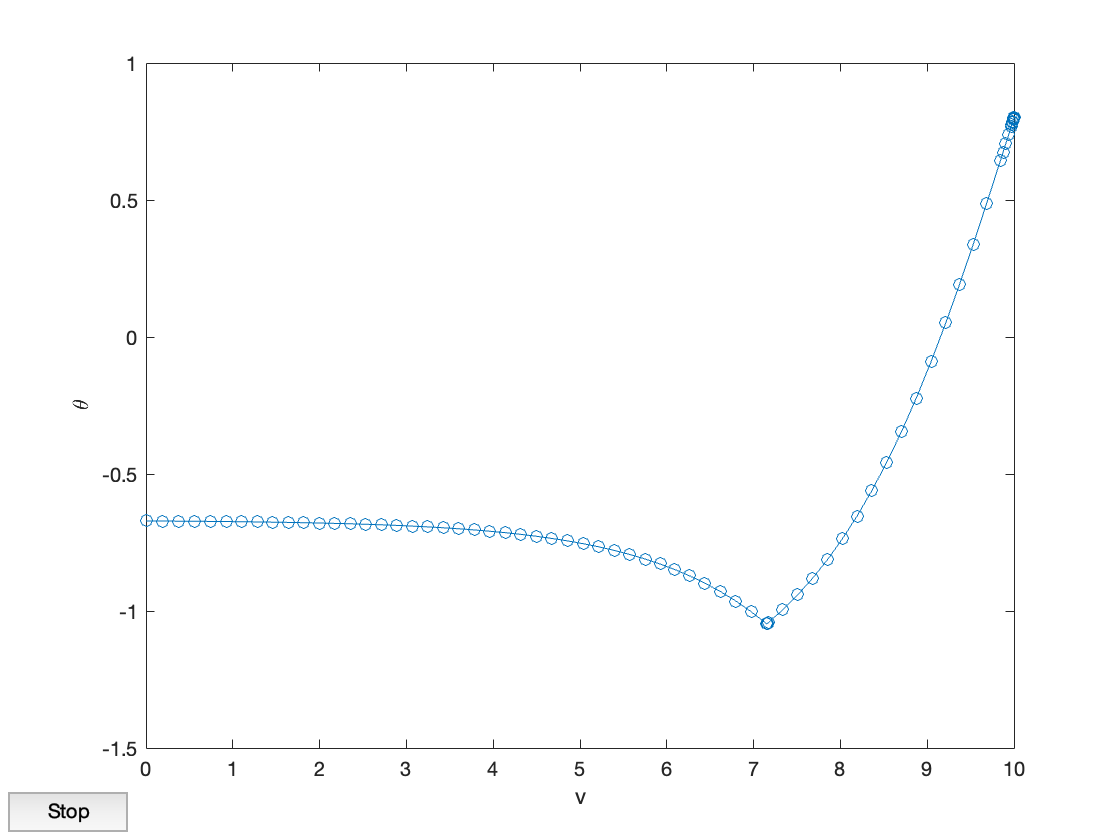

hold off


%ICs =  [-0.4416    1.0272];
ICs = [0 0.8 ];


     [x, imp]  =run_back_with_plot...
        (ICs, 10, @reset_map, @impact, @(t, y) eom(t, y));
         hold on

hold off
         %ICs = [-1.2564 -0.2525];
         %ICs = [-1.3765 -1.0201];
        % ICs = [-1 0.2];
       % ICs = [-0.8611 0.3686];
        ICs = [1 0.8]

ICs =     1.0000    0.8000


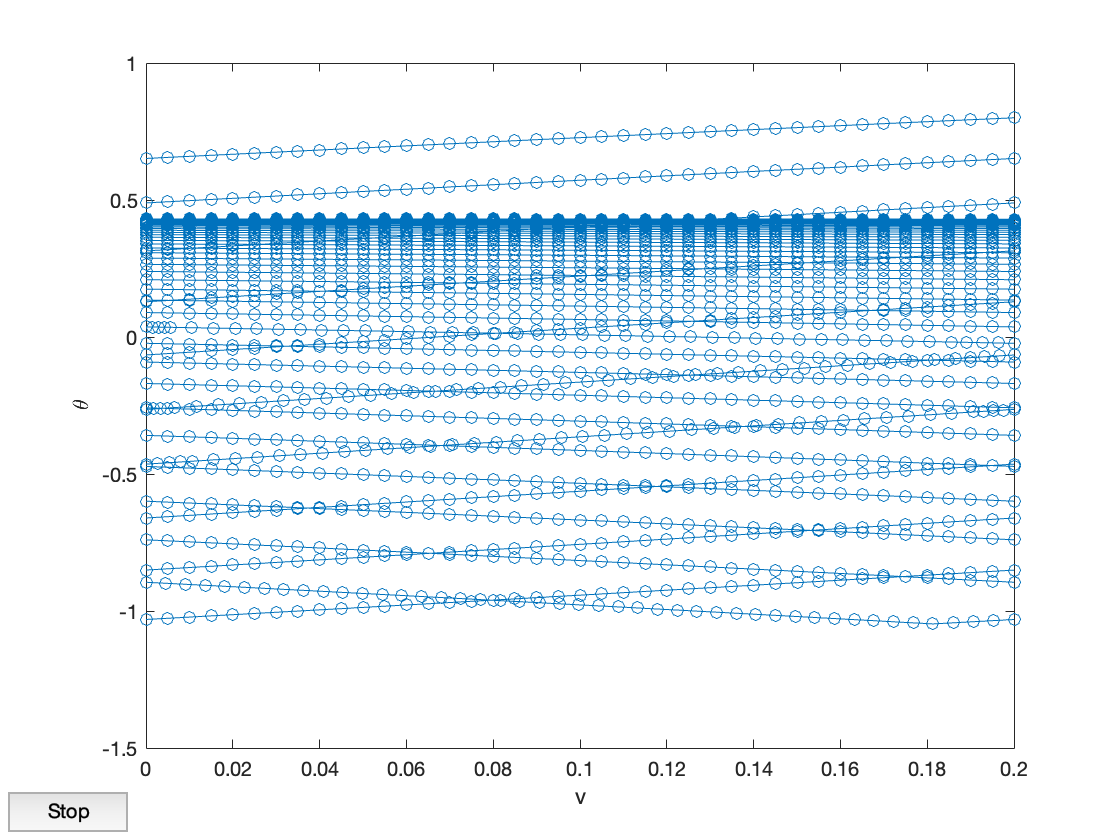


          current_traj = ICs;
          impacts_on_traj = [];
          length = 1;
         sgn = 1;
     while length < 50
          
          % run one time step
          [x_old, is_impact, sgn]  = run_back_with_plot...
              (ICs, dt, @ reset_map, @impact,... 
              @(t, y) eom(t, y).*[1; sgn]);
         % @(t, y) eom(t, y).*[1; 1 - 2*is_impact])
          hold on
         
          % determine position on grid
          current_traj = [current_traj; x_old];
          impacts_on_traj = [impacts_on_traj, is_impact];
          ICs = x_old;
         
         length = length + 1;
      end

u_val = zeros(length, 1);

sgn =      1    -1


sgn = -1

 u_val(length) = initial_density(...
                        current_traj(end, :));
  for k = length - 1:-1:1
          u_val(k) = u_val(k + 1) + dt*div_X(current_traj(k, :),...
                  u_val(k + 1)*(1 - impacts_on_traj(k)*(...
                  1 - hybrid_jacobian(current_traj(k, :)))));
  end

Plot the result


 
 if dims == 3
    figure
    [X, Y] = meshgrid(grid(1, :), grid(2, :));
    for t = 1:N_T
        surf(X, Y, reshape(u(t, :, :, 5),N, N));
        %axis([-2 2 -2 2 0 0.6]);
        view([0, 90]);
        hold off

        pause(.1)
    end
 end

 if dims == 2
     figure 
     % get rid of upper half corner for reduced SIR
     %for t = 1:N_T
     %    for i = 1:N
     %        for j = N - i + 1:N
     %            u(t, i, j) = NaN;
     %        end
     %    end    
     %end
     [Y, X] = meshgrid( grid(2, :), grid(1, :));
     %for t = 1:N_T
     t = 1;
        surf(X, Y, reshape( u(t, :, :), N, N), 'EdgeColor','none');
        %set(gca,'ColorScale','log')
         axis([-sqrt(2) sqrt(2) -pi/3 pi/3]);
         view([0 90]);
         %grid off
         title(sprintf("t = %.2f", t/N_T*T));
         xlabel("$v$", 'Interpreter','latex');
         ylabel("$\theta$", 'Interpreter','latex');
         shading interp
         colorbar
         %saveas(gcf, "reduced_chap_1-non-log.png")
         hold off
         pause(.1)
     %end
 end

Here we define all the functions we need:

- the equations of motion

function dydx = eom(t, y)
    dydx = zeros(size(y));
 
    %% bouncing ball equations
     m = 1; g = 1;
     dydx(1) = y(2)/m;
     dydx(2) = -m*g;

    %% chaplygin sleigh equations
     % m = 1; I = 1; a = 1;
     % dydx(1) = a*y(2)^2;
     % dydx(2) = - (m*a)/(I + m*a^2)*y(1)*y(2);
    % dydx(3) = y(2);

    %% energy surface chaplygin sleigh
    % m = 1; I = 1; a = 1; E = 1;
    % C1 = 2*E/(I + m*a^2); C2 = m/(I + m*a^2);
    % dydx(1) = a*(C1 - C2*y(1)^2);
    % dydx(2) = sqrt(abs(C1 - C2*y(1)^2));

    %% SIR model equations for S, I, N
    % b = 1; g = 1; d = 1; mu = 1;
    % dydx(1) =  - b*y(1)*y(2)/y(3) + mu*y(3) -mu*y(1);
    % dydx(2) = b*y(1)*y(2)/y(3) - ...
     %  (g + mu + d) * y(2);
     % dydx(3) = -d*y(2);
     %dydx(3) = g*y(2) - mu*y(3) + g*y(2)*y(3);

     %% reduced SIR
     %b = 0.1; g = 0.1; d = 0.2; mu = 0.1;
     %if y(1) > 0 && y(2) < 1
     %dydx(1) = (d - b)*y(2)*y(1) + mu  - mu*y(1);
    % dydx(2) = d*y(2)^2 - (d + g + mu)*y(2) + b*y(1)*y(2);
    % else
          %if we are here than we are outside the allowed 
         % percentage range
       %  dydx(1) = 0; dydx(2) = 0;
    % end
    %% matrix groups 

end

- the impact map

function [position,isterminal,direction] = impact(t, y)
    %% bouncing ball
     position = y(1);
     isterminal = 1;
     direction = -1;

    %% chaplygin sleigh
    %theta_0 = pi/3;
    %position = (y(3) - theta_0) *(y(3) + theta_0); 
    %isterminal = 1;  
    %direction = 1;

    %% reduced chaplygin
     %theta_0 = pi/3;
    % position = (y(2) - theta_0) *(y(2) + theta_0); 
    % isterminal = 1;  
    % direction = 1;

    %% SIR 
    % a = .7;
    % position = y(2) - a;
    % isterminal = 1;
    % direction = 0;
end

- the reset map

function y_plus = reset_map(y)
    y_plus = zeros(size(y));

    %% bouncing ball
      y_plus(1) = y(1);
      y_plus(2) = -y(2);

    %% chaplygin sleigh
    % y_plus(1) = y(1);
    % y_plus(2) = -y(2);
    % y_plus(3) = y(3);

    %% reduced chaplygin sleigh
    % y_plus(1) = y(1);
    % y_plus(2) = y(2);

    %% SIN
    % f = 0.3;
    % y_plus(1) = y(1);
    % y_plus(2) = (1 - f)*y(2);
    % y_plus(3) = y(3);

     %% reduced SIR
     %f = 0.3;
     %y_plus(1) = y(1);
     % y_plus(2) = (1 - f) *y(2);
end

- initial density

function rho = initial_density(x)
    % bouncing ball
     rho = exp(-(x(1) - 1)^2 - x(2)^2);

    % SIR
    % rho =  exp(-(x(1) - 0.5)^2 - (x(2) - 0.5)^2 - ...
     %    (x(3) - 100)^2);

    % chaplygin sleigh and reduced chaplygin
    % rho = exp(-sum(x.^2));

    % reduced SIR
   % if x(1) + x(2) <= 1
   %     rho = exp(-(x(1) - 0.5)^2 - 10*(x(2) - 1 + x(1))^2);
   % else
   %     rho = 0;
   % end
  
end

- divergence function 

function div = div_X(y, u)
 % this function takes in a position y and the value
 % of the solution u, and returns the right hand side
 % of the Hybrid transfer PDE (4.4 in the paper) 
 % i.e. div = -u*div_\mu(y)
    %% bouncing ball 
      div = 0;

    %% chaplygin sleigh
    % m = 1; a = 1; I = 1;
    % div = - m*a/(I + m*a^2)*y(1)*u;

    %% reduced chaplygin
    % m = 1; I = 1; a = 1; E = 3;
    % C1 = 2*E/(I + m*a^2); C2 = m/(I + m*a^2);
    % div =  2*a*C2*y(1)*u;

    %% SIR 
     %b = 1; g = 1; d = 1; mu = 1;
     %div = u* (2*mu + g + d + b*(y(1) - y(2))/y(3));

    %% SIR reduced
   % b = 0.1; g = 0.1; d = 0.2; mu = 0.1;
   % div =u*( 2*mu + b*y(2) - 3*d*y(2) + g + d - b*y(1));
end

- a function which determines which grid point is closest to the place where the characteristics intersect the time slice $t-\Delta t$. The information about the grid is passed in gird_info = [N, bounds] a list consisting of a real natural number and a matrix.

function [x_grid, i_grid] = closest_grid_point(x, grid_info)
    % extract information about the grid
    N = grid_info{1};
    bounds = grid_info{2};

    % initialize the point
    x_grid = zeros(size(x));
    i_grid = zeros(size(x));

    % find dimension of input
    dims = size(x);
    dims = dims(2);

    for i = 1:dims
        j = round((x(i) - bounds(i, 1))/(bounds(i, 2) ...
            - bounds(i,1))*(N - 1));
         
        x_grid(i) = bounds(i, 1) + j * (bounds(i, 2) ...
            - bounds(i ,1))/(N - 1);
        i_grid(i) = j + 1;
    end
end


- function that runs the characteristic backward for $\Delta \;t$ and returns the value at $t$ and the number of impacts that have occured:

% first line is for reduced chaplygin
%function [x, impact, sgn] = run_backward(x_now, dt, reset_map,...
%    impact, eom)
function [x, impact] = run_backward(x_now, dt, reset_map,...
    impact, eom)

    % sgn only for reduced chaplygin
    opts = odeset('Events', impact);
    impact = 0;
    % for bouncing ball
    %if x_now(1) < 0.00001 && x_now(2) > 0 
    %    x_now(2) = - x_now(2);
    %end

    [t, y] = ode45(eom, [dt, 0], x_now, opts);           

    % apply the reset map
    IC = y(end, :);
    t = t(end);
     % for reduced chaplygin 
    % eom = @(t, y) eom(t, y).*[1; -1];

    IC = reset_map(IC);
    % keep integrating until another impact happens and repeat
    % procedure
    while t > 0
        [t, y] = ode45(eom, [t, 0], IC, opts);
        IC = y(end, :);            
        t = t(end);
      
        % for reduced chaplygin 
       % eom = @(t, y) eom(t, y).*[1; -1];

        IC = reset_map(IC);    
        impact = impact + 1;
        hold on;
    end
    x = y(end, :);
    % only for reduced chaplygin
    %sgn = sign(eom(2, IC));
    %sgn = sgn(2);
end


- hybrid jacobian function

function hj = hybrid_jacobian(x)
    % bouncing ball, chapplygin sleigh
     hj = 1;

    % reduced chaplygin
   % hj = -1;

    % SIR
     %f = 0.3;
    % hj = 1 - f;

    %% reduced SIR
    %f = 0.3; b = 0.1; g = 0.1; d = 0.2; mu = 0.1;
    %a = 0.7;
    %hj = -(b*a*x(1) + d*a^2 - (g + ...
    %    mu + d)*a)...
    %    /(-b*a*(1 - f)*x(1) + d*a^2*( 1 -f)^2 - (g + ...
    %    mu + d)*a*(1 - f));

end


- run backward for dt with plotting in the phase space


function [x, impact, sgn] = run_back_with_plot(ICs, dt, reset_map, impact, eom)
    %opt = odeset('Events', impact, 'OutputFcn',@odephas2);%, 'OutputSel', 1);
    opt = odeset('Events', impact, 'OutputFcn',@odeplot ,'OutputSel', 2);
    impact = 0;
    %if ICs(1) < 0.00001 && ICs(2) > 0 
    %    ICs(2) = - ICs(2);
    %end
    
    [t, y] = ode45(eom, [dt, 0], ICs, opt);
    hold on;
    
    
    % apply the reset map
    ICs = y(end, :);
    t = t(end);    
   % ICs = reset_map(ICs);
   
    while t >0
        impact = 1;
        eom = @(t, y) eom(t, y).*[1; -1];
        [t, y] = ode45(eom, [t, 0], ICs, opt);
        ICs = y(end, :);            
        t = t(end);
        %ICs = reset_map(ICs);  
        %hold off
        
        hold on;
    end
    x = y(end, :);
    sgn = sign(eom(2, ICs));
    sgn = sgn(2);
    ylabel("$\theta$", Interpreter='latex');
    xlabel("v");
    %xlabel("t");
    %ylabel("$\theta$", "Interpreter","latex");
end